% Plant
A_hor = [-1/t_V,  0, 0, 0, 0;
          cm(1)/I_yz_lookup(1), 0, 0, 0, 0;
          0, 1, 0, 0, 0;
          0, 0, 0, 0, 1;
          0, 0, T_max/m(1), 0, 0];

b_hor = [1/t_V; 0; 0; 0; 0];
Ts_hor = 1/(100);

Rate controller

% Requirments
zeta = 1;
ts2 = 1;
wn = 4/(zeta*ts2);


p_s_want = [-zeta*wn + 1i*wn*sqrt(1-zeta^2);
            -zeta*wn - 1i*wn*sqrt(1-zeta^2)];

p_z_want = exp(p_s_want*Ts_hor);

% Plant
c_rate = [0, 1, 0, 0, 0];
d_rate = 0;
sysC_rate = ss(A_hor,b_hor,c_rate,d_rate)

sysC_rate =
 
  A = 
            x1       x2       x3       x4       x5
   x1      -10        0        0        0        0
   x2  0.03872        0        0        0        0
   x3        0        1        0        0        0
   x4        0        0        0        0        1
   x5        0        0    15.62        0        0
 
  B = 
       u1
   x1  10
   x2   0
   x3   0
   x4   0
   x5   0
 
  C = 
       x1  x2  x3  x4  x5
   y1   0   1   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



% pls = pole(sysC)
% zers = zero(sysC)
% sysD_rate = c2d(sysC,Ts_hor,'zoh');

% Controller
Ki = 14.8

Ki = 14.8000

Kp = Ki*11

Kp = 162.8000

% Ki = 22.39
% Kp = Ki*8.9
C_rate = pid(Kp,Ki,0,0);
% [C_rate,info] = pidtune(sysD_rate,'PI')

sysFB = feedback(C_rate*sysC_rate,1)

sysFB =
 
  A = 
            x1       x2       x3       x4       x5       x6
   x1        0        0        1        0        0        0
   x2     -148      -10    -1628        0        0        0
   x3        0  0.03872        0        0        0        0
   x4        0        0        1        0        0        0
   x5        0        0        0        0        0        1
   x6        0        0        0    15.62        0        0
 
  B = 
       u1
   x1   0
   x2  10
   x3   0
   x4   0
   x5   0
   x6   0
 
  C = 
          x1     x2     x3     x4     x5     x6
   y1   14.8      0  162.8      0      0      0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



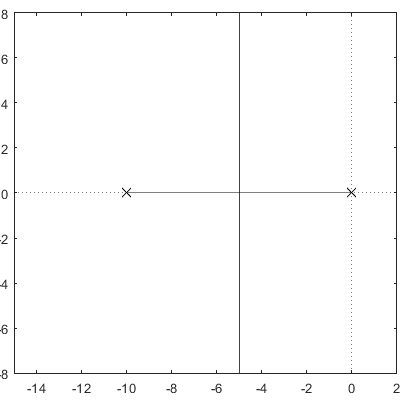

P_cl = rlocus(sysFB,1);
black_rlocus(sysC_rate,[])

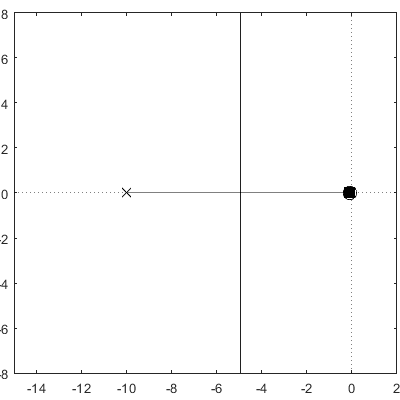

black_rlocus(C_rate*sysC_rate,P_cl)

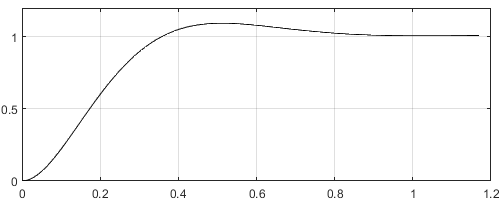

black_step(sysFB)


% Equivalent plant
A_rate = [A_hor-b_hor*C_rate.Kp*c_rate, b_hor*C_rate.Ki;
         -c_rate              , 0]

A_rate = 	1.0e+03 *

   -0.0100   -1.6280         0         0         0    0.1480
    0.0000         0         0         0         0         0
         0    0.0010         0         0         0         0
         0         0         0         0    0.0010         0
         0         0    0.0156         0         0         0
         0   -0.0010         0         0         0         0


b_rate = [b_hor*C_rate.Kp;1]

b_rate =         1628
           0
           0
           0
           0
           1


Angle controller

% Requirments
zeta = 1;
ts2 = 1;
wn = 4/(zeta*ts2);

p_s_want = [-zeta*wn + 1i*wn*sqrt(1-zeta^2);
            -zeta*wn - 1i*wn*sqrt(1-zeta^2)];

p_z_want = exp(p_s_want*Ts_hor);

% Plant
c_ang = [0, 0, 1, 0, 0, 0];
d_ang = 0;
sysC_ang = ss(A_rate,b_rate,c_ang,d_ang);

sysC_ang =
 
  A = 
            x1       x2       x3       x4       x5       x6
   x1      -10    -1628        0        0        0      148
   x2  0.03872        0        0        0        0        0
   x3        0        1        0        0        0        0
   x4        0        0        0        0        1        0
   x5        0        0    15.62        0        0        0
   x6        0       -1        0        0        0        0
 
  B = 
         u1
   x1  1628
   x2     0
   x3     0
   x4     0
   x5     0
   x6     1
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   0   0   1   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



% pls = pole(sysC)
% zers = zero(sysC)
% sysD_ang = c2d(sysC,Ts_hor,'zoh');

% Controller
Kp = 2.25;
C_ang = pid(Kp,0,0,0);
% [C_ang,info] = pidtune(sysD_ang,'P')

sysFB = feedback(C_ang*sysC_ang,1)

sysFB =
 
  A = 
            x1       x2       x3       x4       x5       x6
   x1      -10    -1628    -3663        0        0      148
   x2  0.03872        0        0        0        0        0
   x3        0        1        0        0        0        0
   x4        0        0        0        0        1        0
   x5        0        0    15.62        0        0        0
   x6        0       -1    -2.25        0        0        0
 
  B = 
         u1
   x1  1628
   x2     0
   x3     0
   x4     0
   x5     0
   x6     1
 
  C = 
         x1    x2    x3    x4    x5    x6
   y1     0     0  2.25     0     0     0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



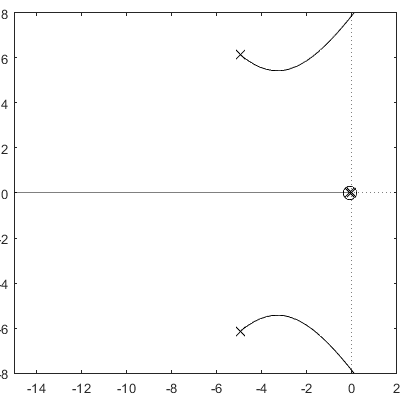

P_cl = rlocus(sysFB,1);
black_rlocus(sysC_ang,[])

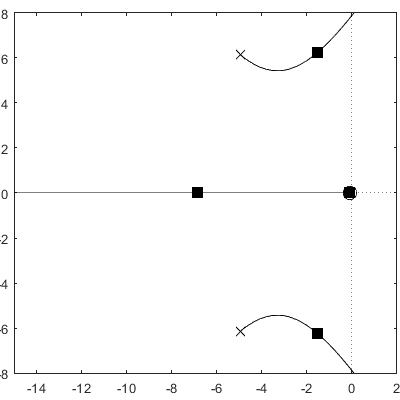

black_rlocus(C_ang*sysC_ang,P_cl)

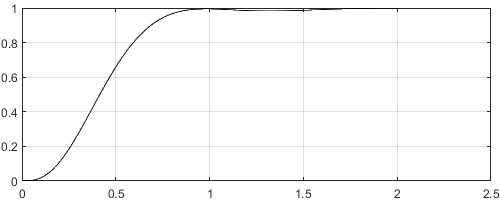

% black_rlocus_fine(C_ang*sysC_ang,P_cl)
black_step(sysFB)


% Equivalent plant
A_ang = A_rate - b_rate*C_ang.Kp*c_ang;
b_ang = b_rate*(C_ang.Kp/T_max);

 Velocity controller

% Requirments
zeta = 1;
ts2 = 3;
wn = 4/(zeta*ts2);

p_s_want = [-zeta*wn + 1i*wn*sqrt(1-zeta^2);
            -zeta*wn - 1i*wn*sqrt(1-zeta^2)];

p_z_want = exp(p_s_want*Ts_hor);

% Plant
c_vel = [0, 0, 0, 0, 1, 0];
d_vel = 0;

sysC_vel = ss(A_ang,b_ang,c_vel,d_vel);

sysC_vel =
 
  A = 
            x1       x2       x3       x4       x5       x6
   x1      -10    -1628    -3663        0        0      148
   x2  0.03872        0        0        0        0        0
   x3        0        1        0        0        0        0
   x4        0        0        0        0        1        0
   x5        0        0    15.62        0        0        0
   x6        0       -1    -2.25        0        0        0
 
  B = 
            u1
   x1    3.663
   x2        0
   x3        0
   x4        0
   x5        0
   x6  0.00225
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   0   0   0   0   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



% pls = pole(sysC)
% zers = zero(sysC)
% sysD_vel = c2d(sysC,Ts_hor,'zoh');

% Controller

Ki = 1.5

Ki = 1.5000

Kp = Ki*65

Kp = 97.5000

% Ki = 8.6063
% Kp = Ki*5.7
C_vel = pid(Kp,Ki,0,0)

C_vel =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 97.5, Ki = 1.5
 
Continuous-time PI controller in parallel form.



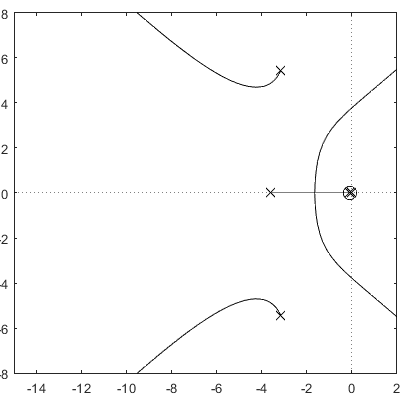

% [C_vel,info] = pidtune(sysD_vel,'PI',1)
sysFB = feedback(C_vel*sysC_vel,1);
P_cl = rlocus(sysFB,1);
black_rlocus(sysC_vel,[])

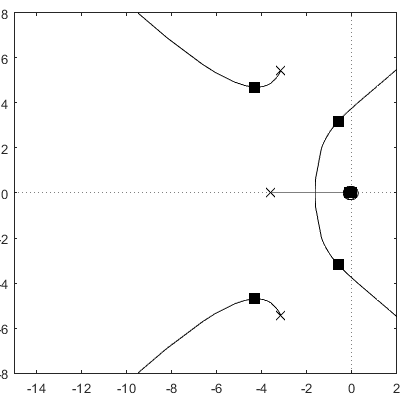

% black_rlocus_fine(sysC_vel,[])
black_rlocus(C_vel*sysC_vel,P_cl)

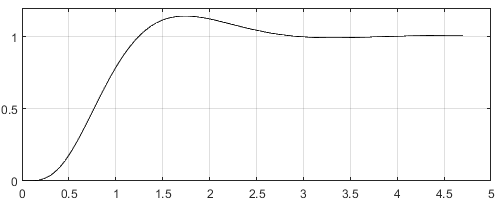

% black_rlocus_fine(C_vel*sysC_vel,P_cl)
black_step(sysFB)


% Equivalent plant
A_vel = [A_ang-b_ang*C_vel.Kp*c_vel, b_ang*C_vel.Ki;
         -c_vel              , 0];
b_vel = [b_ang*C_vel.Kp;1];

Position controller

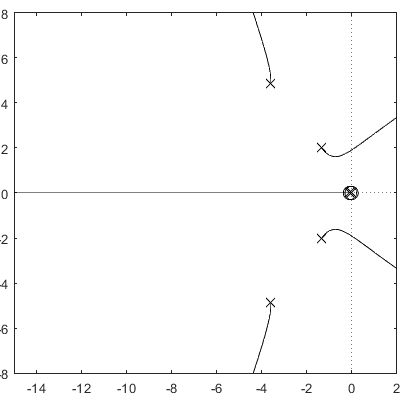

% Requirments
zeta = 1;
ts2 = 5;
wn = 4/(zeta*ts2);

p_s_want = [-zeta*wn + 1i*wn*sqrt(1-zeta^2);
            -zeta*wn - 1i*wn*sqrt(1-zeta^2)];

p_z_want = exp(p_s_want*Ts_hor);

% Plant
c_pos = [0, 0, 0, 1, 0, 0, 0];
d_pos = 0;

sysC_pos = ss(A_vel,b_vel,c_pos,d_pos);
% pls = pole(sysC)
% zers = zero(sysC)
% sysD_pos = c2d(sysC,Ts_hor,'zoh');

% Controller
Kp = 0.55;
C_pos = pid(Kp,0,0,0);
sysFB = feedback(C_pos*sysC_pos,1);
P_cl = rlocus(sysFB,1);
black_rlocus(sysC_pos,[])

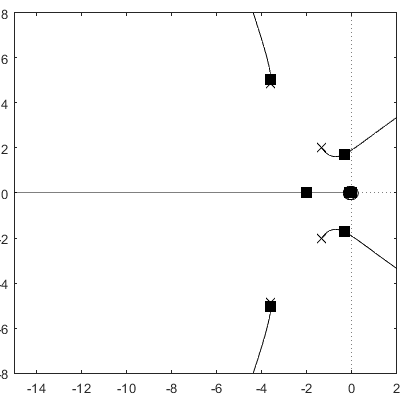

black_rlocus(C_pos*sysC_pos,P_cl)

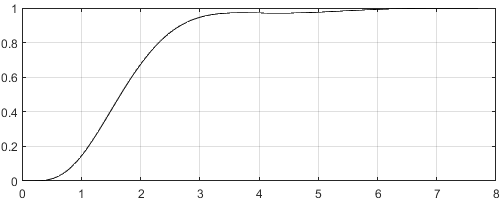

% black_rlocus_fine(C_pos*sysC_pos,P_cl)
black_step(sysFB)